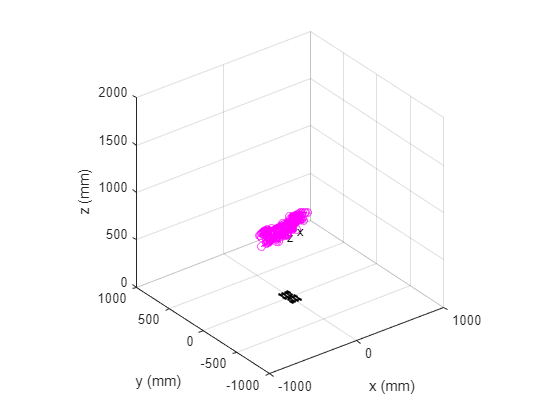

Discarding frame 394
Discarding frame 722
Discarding frame 729
Discarding frame 736
Discarding frame 760
Discarding frame 783
Discarding frame 794
Discarding frame 811
Discarding frame 812
Discarding frame 815
Discarding frame 818
Discarding frame 824
Discarding frame 827
Discarding frame 831
Discarding frame 833
Discarding frame 835
Discarding frame 840
Discarding frame 900
Discarding frame 904
Discarding frame 905


%% ROS initialisations

clear all

%create ros node
camNode = ros2node('cam_node');

%create ros publishers
%imgPub = ros2publisher(camNode, '/img', "sensor_msgs/Image");
p3pPub = ros2publisher(camNode, '/p3p', "geometry_msgs/PoseStamped", Reliability="besteffort");

%create ros2 message
%imgMsg = ros2message("sensor_msgs/Image");
p3pMsg =  ros2message("geometry_msgs/PoseStamped");
send(p3pPub, p3pMsg);
%%

%% Camera initialisations

%% intrinsics
K = [ 267.7991 0 159.5525; 0 278.1177 109.0253; 0 0 1]; %esp32cam low res
imageSize=[240 320];

%create ip cam
cam = ipcam('http://192.168.0.103:81/stream');
%img = imread(fullfile('C:\Users\Alyssa\OneDrive - University of Cape Town\Projects\MSc\QuadStateEstimator\QuadSimEnv\Results\Traj-0007\3750.jpg'));

%p3p variables
p3pResult = struct();
inlierThreshold = 0.5;
rtRounding = 10;
%% Map initialisations

%INITIALISE WORLD MAP
map = load('./Resources/map.mat');

%Checkerboard variables
X_pnts_W = map.worldObjectStruct.checkers.Corners/1000; %in m
checkerSize = map.worldObjectStruct.checkers.NumSquares;
checkerEdgeLength = map.worldObjectStruct.checkers.SquareSize; %mm
checker_w_mm = 31*checkerSize(2);
checker_h_mm = 31*checkerSize(1);

%Known coordinate transformations (mapping)
R_uw2rw = map.worldObjectStruct.transforms.rotm_sim2world;
Rt_imu2rq = map.worldObjectStruct.transforms.rt_imu2genquad;

%plot
plotStruct = initPlots('KneipN');
p3pPlotting.addCheckerboard(plotStruct.traj.Ax, X_pnts_W);
%% Data


%% Run p3p

for i=1:1000
    %get image
    [imgRGB, timestamp] = snapshot(cam);
    img = rgb2gray(imgRGB);

    %Detect checkerboard corners
    [x_pnts_i, checkerSize_detected] = detectCheckerboardPoints(img);
    x_pnts_i = transpose(x_pnts_i);    
    
    %discard any frames where too few corners have been detected
    if (checkerSize_detected(1) ~= checkerSize(1)) || (checkerSize_detected(2) ~= checkerSize(2))
        disp(strcat("Discarding frame ", string(i)));
        continue;
    end
    
    p3pResult = runP3P(p3pResult, i, x_pnts_i, X_pnts_W, K, imageSize, checkerSize, inlierThreshold, rtRounding,  'KneipN');
    plotStruct.traj = updatePlot(plotStruct.traj, p3pResult);

    %Display checkerboard image for this iteration - for troubleshooting
    % if (checkerSize_detected(1) <= checkerSize(1)) || (checkerSize_detected(2) <= checkerSize(1)) 
    %     if i==1
    %         checkerFig = figure();
    %         checkerAx = axes('Parent', checkerFig);
    %         checkerImg = imshow(imgFuncs.markDetectedCheckers(img, x_pnts_i), 'Parent', checkerAx);
    %     else
    %         checkerImg.CData = (imgFuncs.markDetectedCheckers(img, x_pnts_i));
    %         drawnow;
    %     end 
    % end

    %extract time
    timestamp_arr = datestr(timestamp, 'YYYY/mm/dd HH:MM:SS:FFF');
    timestamp_split = strsplit(timestamp_arr, ':');
    timestamp_s = str2double(timestamp_split{3});
    timestamp_ms = str2double(timestamp_split{4});
    timestamp_ns = timestamp_ms * 1000000;
    
    %populate p3p message
    orient = rotm2quat(p3pResult.KneipN.Rt(1:3, 1:3, end));
    p3pMsg.pose.position.x = p3pResult.KneipN.Rt(1, 4, end);
    p3pMsg.pose.position.y = p3pResult.KneipN.Rt(2, 4, end);
    p3pMsg.pose.position.z = p3pResult.KneipN.Rt(3, 4, end);
    p3pMsg.pose.orientation.w = orient(1);
    p3pMsg.pose.orientation.x = orient(2);
    p3pMsg.pose.orientation.y = orient(3);
    p3pMsg.pose.orientation.z = orient(4);
    p3pMsg.header.stamp.sec = int32(timestamp_s);
    p3pMsg.header.stamp.nanosec = uint32(timestamp_ns);

    send(p3pPub, p3pMsg);

end